# Procedure 2 for Closed Koopman System

clear; close all; clc;
set(0,'DefaultLineLineWidth',2.5) 
set(0,'defaultfigurecolor',[1 1 1])

## Dynamics

## 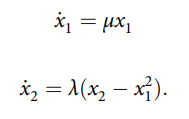

mu=0.2; 
lambda =-0.5;

f = @(t, x)[mu*x(1,:);  lambda*(x(2,:)-x(1,:).^2)];

## Plot uncontrolled response of the system

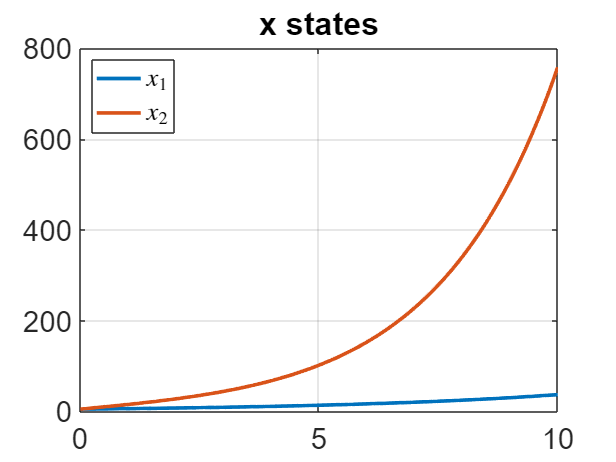

n=2; % dimension
tSpan = 0:0.02:10; ic = [5,5]';
[T, x_uncontrolled] = ode45(@(t,x)f(0,x), tSpan, ic);
close all
figure()
plot(T, x_uncontrolled(:,1:n))
grid on;
title('x states')
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$','Location','northwest');
set(LEG,'interpreter','latex');

## Linearization of the system

x = sym('x',[n;1]);
x0 = [0;0];

A0 = double(subs(jacobian(f(0,x),x),x,x0)); 
g0 = [1; 0]; %assume constant B with scalar u acting on x1 state

%linear eigenfunctions realization from complex eigenfunctions
[~,D1,W1] = eig(A0);
[W, D] = cdf2rdf(W1, D1);

## Construct the Hamiltonain system

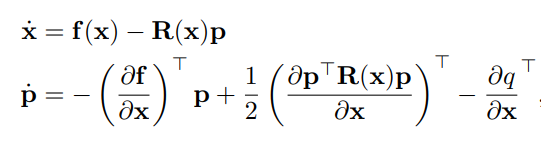 (eqn 75)

(eqn 76)

xp = sym('x',[2*n;1]); 
up = sym('up',[1,1]);

f_sym = f(0,xp(1:4));
%g= fu(0,xp(1:4));
g = g0;
Df  = jacobian(f_sym ,xp(1:n));
R_x = g*g'; %R(x)
R_0 = g0*g0'; %R(0)

q_x = 1/2*(xp(1)^2+xp(2)^2);
Dq  = jacobian(q_x,xp(1:n));
DDq = hessian(q_x,xp(1:n));

p = xp(n+1:end);
p1 = jacobian(p'*R_x*p, xp(1:n));

H_sym =  [f_sym-R_x*xp(n+1:end);  -Df'*xp(n+1:end)+0.5.*p1'-Dq']; 
H_sys = matlabFunction(H_sym, 'Vars',{xp(1:2*n),up}); %equation 75

A = [A0, -R_0; -double(DDq), -A0']; %equation 76

## Plot uncontrolled response of Hamiltonain system

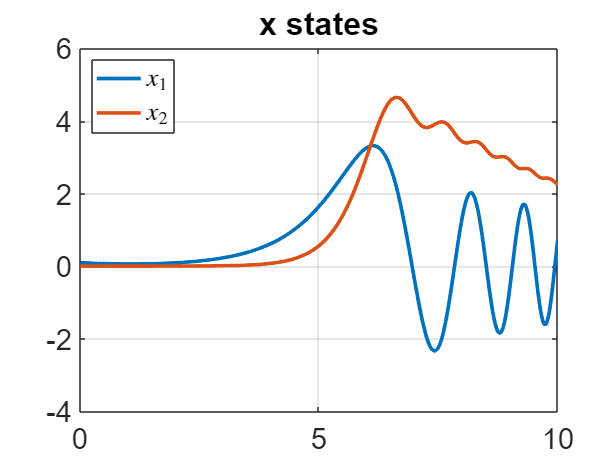

tSpan = 0:0.02:10; ic = [0.1,0,0.1,0]';
[T, x_uncontrolled] = ode45(@(t,x)H_sys(x, 0), tSpan, ic);
close all
figure()
plot(T, x_uncontrolled(:,1:n))
grid on;
title('x states')
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$','Location','northwest');
set(LEG,'interpreter','latex');

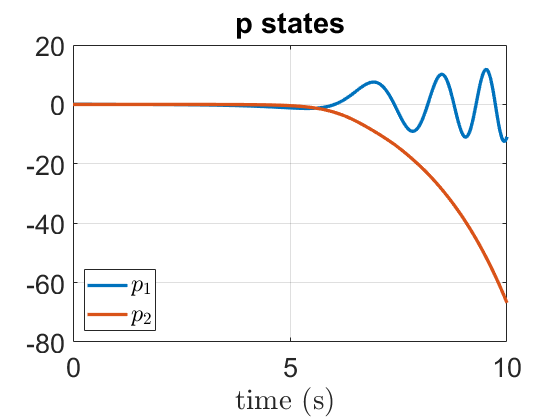

figure()
plot(T, x_uncontrolled(:,n+1:2*n))
grid on;
title('p states')
xlabel('time (s) ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$p_1$', '$p_2$','Location','southwest');
set(LEG,'interpreter','latex')

## Parameters setup

Dom = [-10 10]; %Domain
domain = Dom(2)-Dom(1);
scale = @(x) x /domain;

## Collect random initial conditions

% numICs = 1e4; %initial coditions
% X = rand(n,numICs)*2*Dom(2) - Dom(2); %sample initial conditions
% P = X;
% X = [X;P];

## Try some initial conditions and collect X along trajectories 

Skip this if you run the previous section and generated random initial condtions

numICs = 100;
tSpan = 0:0.02:3;
seed = 1; rng(seed)

lenT = length(tSpan);

X = zeros(lenT, 2*n);

count = 1;
for j = 1:100*numICs
    % randomly start from x1range(1) to x1range(2)
    x1 = (domain)*rand+Dom(1);
    x2 = (domain)*rand+Dom(1);
    p1 = (domain)*rand+Dom(1);
    p2 = (domain)*rand+Dom(1);

    ic = [x1; x2; p1; p2];
    [T, temp] = ode45(@(t,x)H_sys(x, 0), tSpan, ic);
    X(1+(count-1)*lenT : lenT + (count-1)*lenT,:) = temp;
    if count == numICs
        break
    end
    count = count + 1;
end
X=X';

## Selet basis functions to approximate h(x)

order = 3; %order poly
[Psi, DPsi] = monomial_basis(order, n); nb_Psi = length(Psi);
x1 = sym('x',[2*n,1]);

%remove linear part, principle eigenfunctions
PsiX = Psi(n+1:end); nb_PsiX = length(PsiX);
DPsiX  = jacobian(PsiX ,x1(1:n)); 

% term 2 of the basis gamma
X_o_P =  kron(x1(1:n), x1(n+1:2*n)); nb_X_o_P = length(X_o_P);
PsiX_o_P = kron(PsiX, x1(n+1:2*n));% term 3 of the basis gamma

Psi_Gamma = [PsiX; X_o_P; PsiX_o_P]; Nb_G=length(Psi_Gamma);
Gamma = matlabFunction(scale(Psi_Gamma),'Vars',{x1});


Psi_DGamma  = jacobian(Psi_Gamma ,x1);
DGamma = matlabFunction(scale(Psi_DGamma),'Vars',{x1});

X_o_DPsiX = matlabFunction(scale(kron(x1(1:n),DPsiX')), 'Vars',{x1(1:n)});
PsiX_o_DPsiX = matlabFunction(scale(kron(PsiX,  DPsiX')), 'Vars',{x1(1:n)});

%for koopman control
PsiX_u = matlabFunction(scale(PsiX),'Vars',{x1(1:n)});
DPsiX_u = matlabFunction(scale(DPsiX),'Vars',{x1(1:n)});

## Solve the least squares problem to estimate U

## Solve the least squares problem to estimate U

E = A;
Ez = E*X; 
G_z = Gamma(X);

F_z = H_sys(X, 0);
Df_z = zeros(Nb_G,1);
for i=1:size(X,2)
    Df_z(:,i) = DGamma(X(:,i))*H_sys(X(:,i),0);
end

%YALMIP
U = sdpvar(2*n,Nb_G);
Objective =  norm(U*Df_z - A*U*G_z + F_z - Ez, 'fro')+ 0.1*norm(U,1);
Constraints = [];

opt = sdpsettings('solver','mosek','verbose',2,'cachesolvers',1);
sol = optimize(Constraints,Objective,opt);

MOSEK Version 9.3.18 (Build date: 2022-3-17 11:29:16)
Copyright (c) MOSEK ApS, Denmark. WWW: mosek.com
Platform: Windows/64-X86

MOSEK warning 62: The A matrix contains a large value of  1.0e+10 in constraint '' (69) at variable '' (7835).
MOSEK warning 62: The A matrix contains a large value of  1.0e+10 in constraint '' (70) at variable '' (7836).
MOSEK warning 62: The A matrix contains a large value of  1.2e+10 in constraint '' (68) at variable '' (7838).
MOSEK warning 62: The A matrix contains a large value of  1.2e+10 in constraint '' (69) at variable '' (7839).
MOSEK warning 62: The A matrix contains a large value of  1.2e+10 in constraint '' (70) at variable '' (7840).
MOSEK warning 62: The A matrix contains a large value of  1.2e+10 in constraint '' (71) at variable '' (7841).
MOSEK warning 62: The A matrix contains a large value of  1.3e+10 in constraint '' (68) at variable '' (7842).
MOSEK warning 62: The A matrix contains a large value of  1.3e+10 in constraint '' (69) at var

U = value(U)

U =     0.0006   -0.1018   -0.0141   -0.0000    0.0001    0.0000    0.0007    0.0048    0.0374    0.0002    0.0174   -0.0000   -0.0001   -0.0000   -0.0002    0.0001   -0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000
   -0.0693   -0.0020   -0.4408    0.0001    0.0000    0.0008    0.0002   -0.0052   -0.0002   -0.0000    0.0132    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0006    0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000    0.0000
    0.0005    0.0050   -0.0059   -0.0000    0.0000   -0.0000   -0.0018   -0.0141   -0.0063   -0.1557   -0.0086    0.0004    0.0000    0.0001    0.0000   -0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   -0.0000    0.0000    0.0000
   -0.0016    0.0008    0.0404    0.0000   -0.0000   -0.0001    0.0000   -0.0256    0.0002    0.0000   -0.1075   -0.0000    0.0002    0.0001    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000   

## Stable and Unstable Manifolds

[~,  D_lineart,  W_lineart] = eig(A);
[W_linear,  D_linear] = cdf2rdf(W_lineart,D_lineart);

%sort eigenvales and eigenvectors
d = diag(D_linear);
[d, ind] = sort(d,'descend');
D_sorted = D_linear(:,ind);
W = W_linear(:, ind);
Lambda = W'*A*inv(W'); %check that unstable eigenvalues are up
Wu1 = W(1:n,1:n);
Wu2 = W(n+1:2*n,1:n);
J1 = -inv(Wu2')*Wu1';

U11 = U(1:n, 1:nb_PsiX );
U21 = U(n+1:2*n, 1:nb_PsiX );
U12 = U(1:n, 1+nb_PsiX:nb_X_o_P+nb_PsiX);
U22 = U(n+1:2*n, 1+nb_PsiX:nb_X_o_P+nb_PsiX);
U13 = U(1:n, 1+nb_PsiX+nb_X_o_P:end);
U23 = U(n+1:2*n, 1+nb_PsiX+nb_X_o_P:end);

A_bar = -Wu1'*U11 - Wu2'*U21;

Bx = @(x) (Wu1'*U12 + Wu2'*U22)*X_o_DPsiX(x) + (Wu1'*U13 + Wu2'*U23)*PsiX_o_DPsiX(x);
%
nb_points = 1e4;
data = rand(2*n, nb_points)*2*Dom(2) - Dom(2);
B_bar = zeros(n,nb_Psi-n);
for i=1:size(data,2)
    B_bar = B_bar +Bx(data(:,i));
end
B_bar = B_bar/size(data,2);

J2 = pinv(B_bar)*A_bar;

## LQR Controller

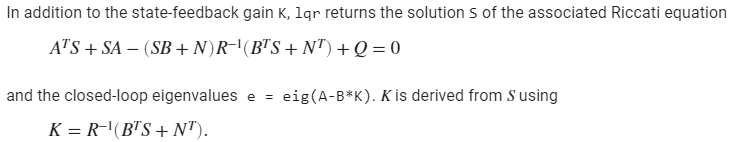

 

Compare matlab's Riccati equation for LQR, we get R_koopman = B_tranpose*inv(R_lqr)*B

Q = eye(n,n); %cost on states
R_lqr = 1;
[K,P,CLP] = lqr(A0,g0,Q,R_lqr);
uLQR = @(x) -K*(x);

## HJ-Koopman Controller:

%uKoop=@(x) -fu(0,x)'*(J1*x + DPsiX_u(x)'*J2*PsiX_u(x));
uKoop=@(x) -g0'*(J1*x + DPsiX_u(x)'*J2*PsiX_u(x));

## Simulation

(change x_initial to simulate response of different initial conditions and plot)

f_u = @(t,x,u)[f(t,x)+g0*u];

deltaT = 0.01; %step-time
tspan = 0:deltaT:5;

options = odeset('RelTol',1e-9,'AbsTol',1e-300);
x_initial = [10;10];

%LQR
[tspan, xLQR] = ode45(@(t,x)f_u(t, x, uLQR(x)), tspan, x_initial, options);

if(abs(xLQR(end,1)) && abs(xLQR(end,2)) <=1e-3)
    disp('LQR succuess')
else
    disp('LQR failed')
end

LQR failed


[tspan1, x_Koop] = ode45(@(t,x)f_u(t, x, uKoop(x)), tspan, x_initial, options);
if(abs(x_Koop(end,1)) && abs(x_Koop(end,2)) <=1e-3)
    disp('HJK succuess')
else
    disp('HJK failed')
end

HJK failed


## Plots

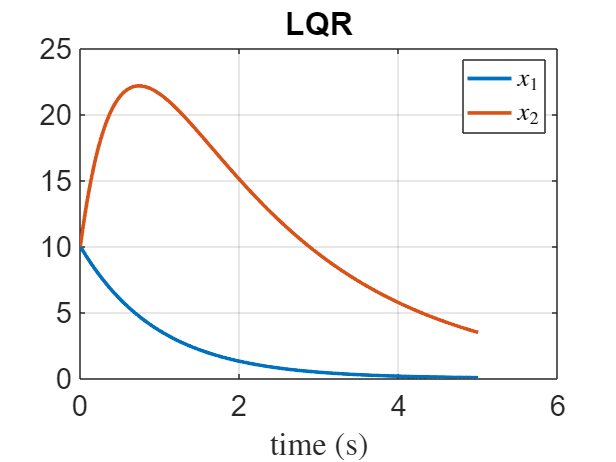

close all
figure(1)
%subplot(2,2,1)
plot(tspan, xLQR)
grid on;
title('LQR')
xlabel('time (s) ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('$x_1$', '$x_2$');
set(LEG,'interpreter','latex')

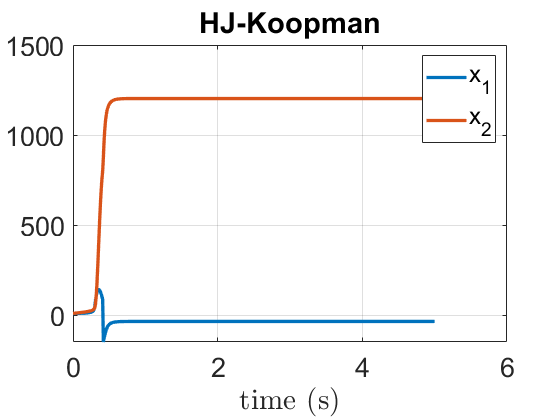

figure(2)
%subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJ-Koopman')
xlabel('time (s)','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('x_1', 'x_2');

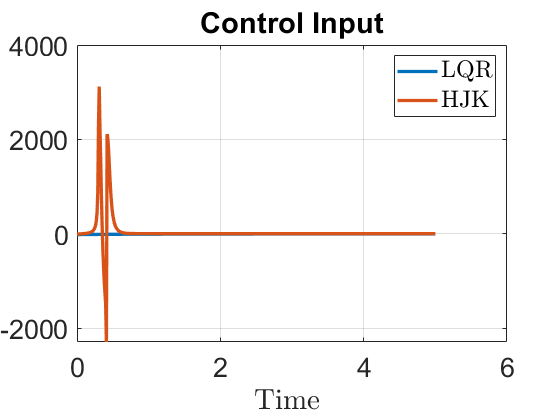

%set(LEG,'interpreter','latex')
figure(3)
%subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

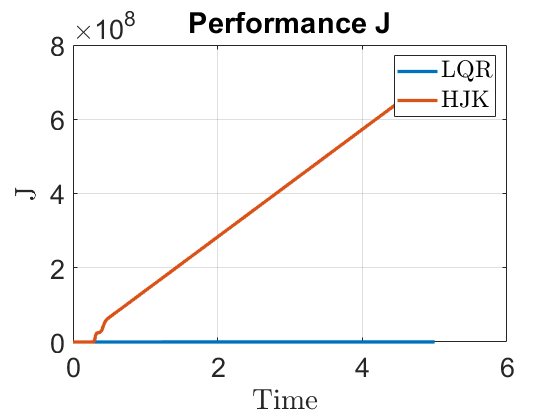

figure(4)
%subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 + U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Performance J')
set(gca,'fontsize',20)
LEG =legend('LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Combined Plots

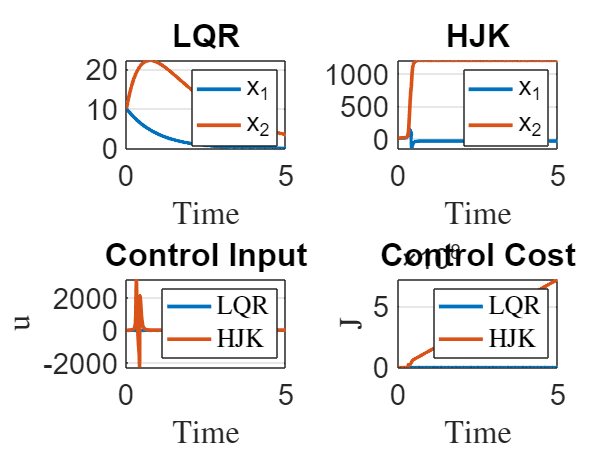

close all  
figure()
subplot(2,2,1)
plot(tspan1, xLQR)
grid on; hold on;
%legend('x_1', 'x_2');xlabel('Time')
title('LQR')
xlabel('Time ','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('x_1', 'x_2');
%set(LEG,'interpreter','latex')

subplot(2,2,2)
plot(tspan1, x_Koop)
grid on;
title('HJK')
xlabel('Time','interpreter','latex');
%ylabel('$x_1$,$x_2$','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('x_1', 'x_2');
%set(LEG,'interpreter','latex')

subplot(2,2,3)
 U_Lqr =zeros(size(xLQR,1),1);
 U_Koop = zeros(size(xLQR,1),1);
for i=1:size(xLQR,1)
    U_Lqr(i) = uLQR(xLQR(i,:)');
    U_Koop(i) =uKoop(x_Koop(i,:)');
end
plot(tspan, U_Lqr, tspan1, U_Koop)
grid on;
title('Input')
ylabel('u','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(gca,'fontsize',20)
LEG = legend('LQR','HJK');
set(LEG,'interpreter','latex')
title('Control Input')

subplot(2,2,4)
JLQR = cumsum(xLQR(:,1).^2 + xLQR(:,2).^2 +U_Lqr.^2);
Jkoopman =  cumsum(x_Koop(:,1).^2 + x_Koop(:,2).^2 + U_Koop.^2 );
plot(tspan, JLQR,tspan, Jkoopman)
grid on;
title('Control Cost')
set(gca,'fontsize',20)
LEG =legend('LQR','HJK');
ylabel('J','interpreter','latex');
xlabel('Time ','interpreter','latex');
set(LEG,'interpreter','latex')

## Monomial Basis

function [Psi, DPsi] = monomial_basis(deg, dim)
%  [Psi, DPsi] = monomial_basis(deg, dim) returns a monomial basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   deg = degree of monomial
%   dim = number of states
k = linspace(2, deg, deg-1);
d = dim;

if (deg == 0)
    Psi = 0;
    for i=1:dim-1
        Psi = [Psi 0];
    end
    DPsi = zeros(dim,dim);
    Psi = Psi';
    
else

    x=sym('x',[d,1]);
    assume(x,'real')
    
    Psi = [x.'];
    for i=1:size(k,2)
        m = nchoosek(k(i)+d-1,d-1); 
        dividers = [zeros(m,1),nchoosek((1:(k(i)+d-1))',d-1),ones(m,1)*(k(i)+d)]; 
        a = diff(dividers,1,2)-1;
        for i = 1:size(a,1)
            Psi = [Psi prod(x.' .^ a(i,:))];
        end
    end
    DPsi = jacobian(Psi,x);
    Psi = Psi';

end

end

## Bernstein Basis

function [Psi,DPsi] = bernstein_basis(order, dim, scale)
%  [Psi, DPsi] = bernstein_basis(deg, dim,scale=0) returns a bernstein basis function and its derivative 
%   There is not a 1 included in Psi, only the linear and higher order terms
%   order = order of bernstein polynomials being fit
%   dim = number of states

if nargin<3
  scale = 0;
end

x=sym('x',[dim,1]);
assume(x,'real')
Psi = [];

if(order==0)
    Psi = 1;
end

for i = 0:order
    m = nchoosek(order,i);
    for j = 1:dim
        %Psi = [Psi; m.*((x(j)+1).^i * (-x(j)).^(order-i))];
        %scale to -2pi to 2pi
        Psi = [Psi; m.*((x(j)+scale).^i * (1-scale-x(j)).^(order-i))];
    end
end

DPsi = jacobian(Psi,x);

end
